# Projeto 

## META 1

## 1


% Criar tabela
caminho = "data/36";
arquivos = dir(caminho);
arquivosFiltrados = arquivos([arquivos.isdir] == 0);
tabela = struct2table(arquivosFiltrados);
% Número de arquivos
nArquivos = height(tabela);

digitos = zeros(nArquivos, 1);
participantes = zeros(nArquivos, 1);
repeticoes = zeros(nArquivos, 1);

for i = 1:nArquivos
    nomeArquivo = tabela.name{i};
    % Remover a extensão (ex.: '.wav')
    [~, nomeSemExt, ~] = fileparts(nomeArquivo);
    % Separar os componentes usando o underline como delimitador
    partes = split(nomeSemExt, '_');
    
    if numel(partes) >= 3
        % Converter os componentes para número
        digitos(i) = str2double(partes{1});
        participantes(i) = str2double(partes{2});
        repeticoes(i) = str2double(partes{3});
    else
        warning('Formato de nome inesperado: %s', nomeArquivo);
        digitos(i) = NaN;
        participantes(i) = NaN;
        repeticoes(i) = NaN;
    end
end

% Criar a nova tabela
novaTabela = table(tabela.folder, tabela.name, participantes, digitos, repeticoes, ...
    'VariableNames', {'Diretorio_Audio', 'Nome_Arquivo', 'Participante', 'Digito', 'Repeticoes'});


## 2


arquivos = dir(fullfile(caminho, "*.wav"));
nomes = {arquivos.name}';
taxasAmostragem = zeros(length(arquivos), 1);
sinais = cell(length(arquivos), 1);

for i = 1:length(arquivos)
    caminhoArquivo = fullfile(arquivos(i).folder, arquivos(i).name);
    [sinal, fs] = audioread(caminhoArquivo);
    taxasAmostragem(i) = fs;
    sinais{i} = sinal;
end

% Criar tabela com os dados
tabArquivos = table(nomes, taxasAmostragem, sinais, ...
    'VariableNames', {'Nome_Arquivo', 'Taxa_Amostragem', 'Sinal'});


## 3

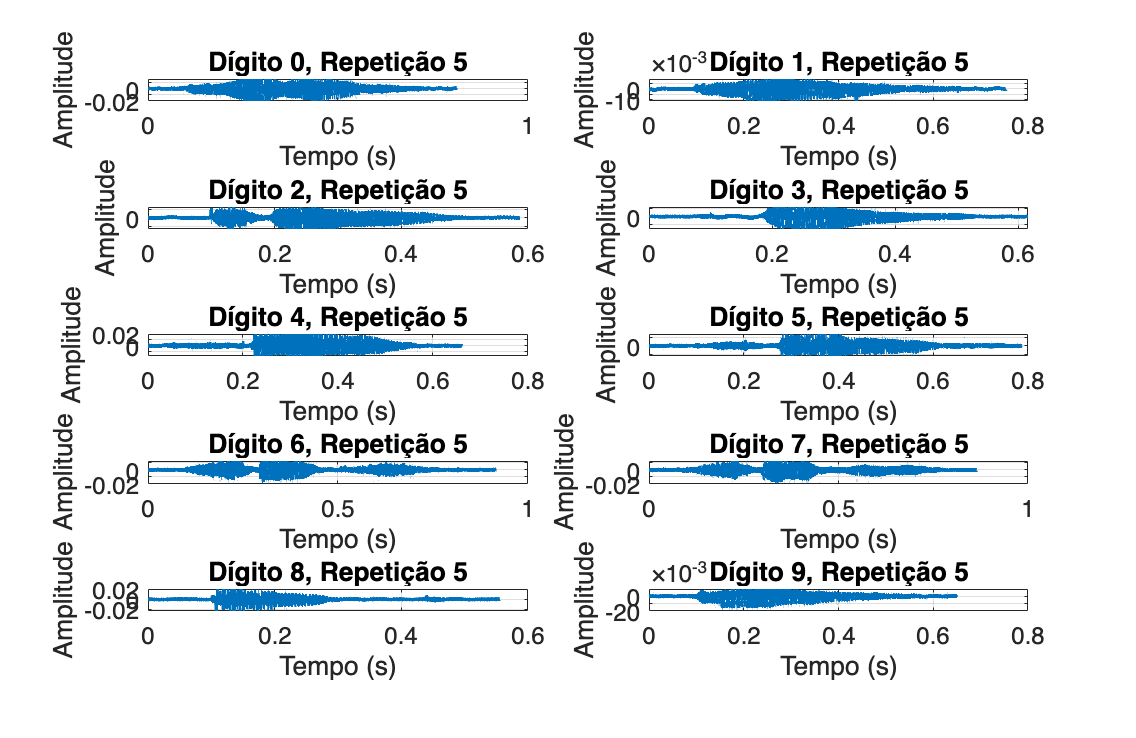


% Extração dos dígitos e repetições
nArquivos = height(tabArquivos);
digitos = zeros(nArquivos,1);
repeticoes = zeros(nArquivos,1);
for i = 1:nArquivos
   [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
   partes = split(nomeSemExt, '_');
   % Primeiro número = dígito
   digitos(i) = str2double(partes{1});
   % Terceiro número = repetição
   repeticoes(i) = str2double(partes{3});
end
tabArquivos.Digito = digitos;
tabArquivos.Repeticao = repeticoes;

% Filtrar apenas a repetição 5
repEscolhida = 5;
T_filtro = tabArquivos(tabArquivos.Repeticao == repEscolhida, :);

% Obter os dígitos disponíveis nessa repetição
digitosUnicos = unique(T_filtro.Digito);
numDigitos = numel(digitosUnicos);

if numDigitos < 1
    error('Nenhum dígito disponível na repetição %d.', repEscolhida);
end

% Dois gráficos por linha
numColunas = 2;
numLinhas = ceil(numDigitos / numColunas);

% Criar figura mais alta
figure('Name', sprintf('Repetição %d', repEscolhida), 'NumberTitle','off', ...
       'Units','normalized', 'OuterPosition',[0 0 1 1]);

% Plot de gráficos
for i = 1:numDigitos
    digitoAtual = digitosUnicos(i);
    
    % Seleciona, para o dígito atual, o primeiro arquivo
    T_atual = T_filtro(T_filtro.Digito == digitoAtual, :);
    
    sinal = T_atual.Sinal{1};
    fs = T_atual.Taxa_Amostragem(1);
    
    % Vetor de tempo para o sinal
    t = (0:length(sinal)-1) / fs;
    
    % Criação do subplot
    subplot(numLinhas, numColunas, i)
    plot(t, sinal, 'LineWidth', 2)
    title(sprintf('Dígito %d, Repetição %d', digitoAtual, repEscolhida), 'FontSize', 12)
    xlabel('Tempo (s)', 'FontSize', 12)
    ylabel('Amplitude', 'FontSize', 12)
    set(gca, 'FontSize', 12)
    grid on
end

## 4


arquivos = dir(fullfile(caminho, "*.wav"));
nomes = {arquivos.name}';
taxasAmostragem = zeros(length(arquivos), 1);
sinais = cell(length(arquivos), 1);

for i = 1:length(arquivos)
    caminhoArquivo = fullfile(arquivos(i).folder, arquivos(i).name);
    [sinal, fs] = audioread(caminhoArquivo);
    
    % Remover silêncio inicial
    limiar = 0.02;
    idx = find(abs(sinal) > limiar, 1, 'first');
    if ~isempty(idx)
        sinal = sinal(idx:end);
    end
    
    % Normalizar amplitude para [-1, 1]
    if max(sinal) ~= min(sinal)
        sinal = 2 * (sinal - min(sinal)) / (max(sinal) - min(sinal)) - 1;
    end
    
    % Ajustar duração para 0.8 segundos
    duracao_alvo = 0.8;
    num_amostras_alvo = round(duracao_alvo * fs);
    if length(sinal) < num_amostras_alvo
        sinal = [sinal; zeros(num_amostras_alvo - length(sinal), 1)];
    elseif length(sinal) > num_amostras_alvo
        sinal = sinal(1:num_amostras_alvo);
    end
    
    taxasAmostragem(i) = fs;
    sinais{i} = sinal;
end

tabArquivos = table(nomes, taxasAmostragem, sinais, ...
    'VariableNames', {'Nome_Arquivo', 'Taxa_Amostragem', 'Sinal'})

tabArquivos = 500×3 table
     Nome_Arquivo      Taxa_Amostragem         Sinal      
    _______________    _______________    ________________

    {'0_36_0.wav' }         48000         {38400×1 double}
    {'0_36_1.wav' }         48000         {38400×1 double}
    {'0_36_10.wav'}         48000         {38400×1 double}
    {'0_36_11.wav'}         48000         {38400×1 double}
    {'0_36_12.wav'}         48000         {38400×1 double}
    {'0_36_13.wav'}         48000         {38400×1 double}
    {'0_36_14.wav'}         48000         {38400×1 double}
    {'0_36_15.wav'}         48000         {38400×1 double}
    {'0_36_16.wav'}         48000         {38400×1 double}
    {'0_36_17.wav'}         48000         {38400×1 double}
    {'0_36_18.wav'}         48000         {38400×1 double}
    {'0_36_19.wav'}         48000         {38400×1 double}
    {'0_36_2.wav' }         48000         {38

## 5

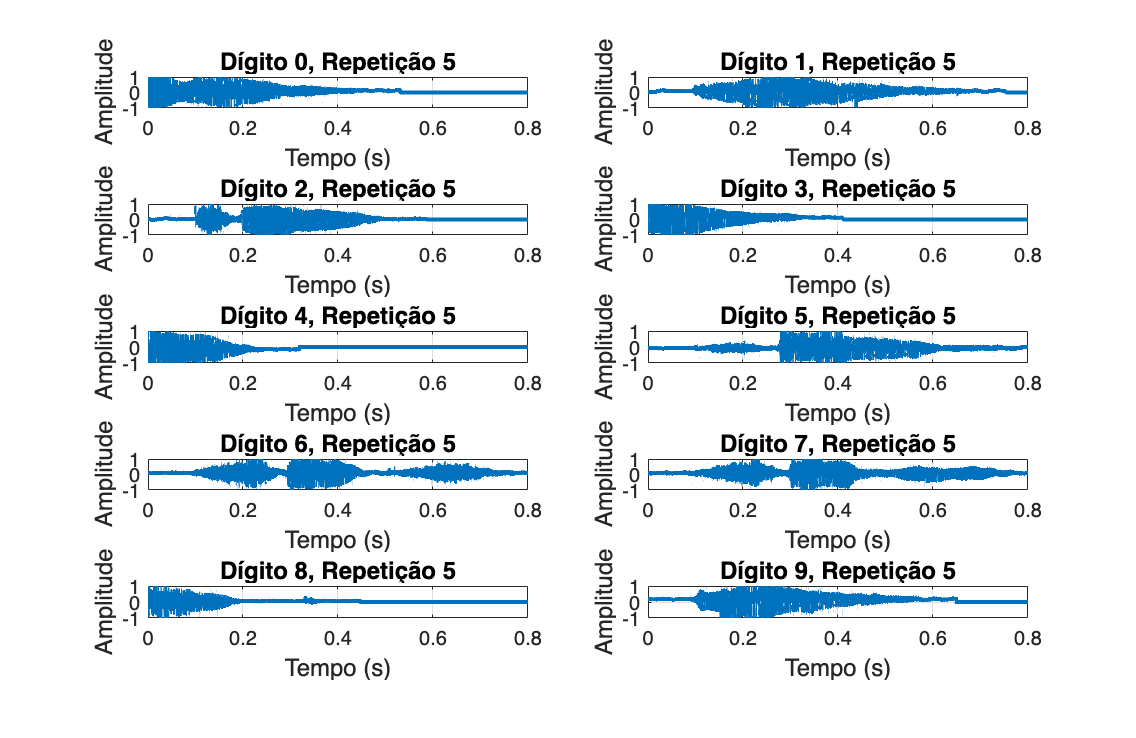


% Extrair dígito e repetição dos nomes dos arquivos
nArquivos = height(tabArquivos);
digitos = zeros(nArquivos,1);
repeticoes = zeros(nArquivos,1);

for i = 1:nArquivos
    [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
    partes = split(nomeSemExt, '_');
    if numel(partes) >= 3
        digitos(i) = str2double(partes{1});
        repeticoes(i) = str2double(partes{3});
    else
        warning('Formato inesperado: %s', tabArquivos.Nome_Arquivo{i});
        digitos(i) = NaN;
        repeticoes(i) = NaN;
    end
end

tabArquivos.Digito = digitos;
tabArquivos.Repeticao = repeticoes;

% Filtrar arquivos da repetição desejada
repEscolhida = 5;
T_filtro = tabArquivos(tabArquivos.Repeticao == repEscolhida, :);
if isempty(T_filtro)
    error('Nenhum arquivo encontrado para a repetição %d.', repEscolhida);
end

% Plotar os sinais para cada dígito
digitosUnicos = unique(T_filtro.Digito);
numDigitos = numel(digitosUnicos);
numColunas = 2;
numLinhas = ceil(numDigitos / numColunas);

figure('Name', sprintf('Sinais - Repetição %d', repEscolhida), 'NumberTitle','off', ...
       'Units','normalized', 'OuterPosition',[0 0 1 1]);

for i = 1:numDigitos
    digitoAtual = digitosUnicos(i);
    T_atual = T_filtro(T_filtro.Digito == digitoAtual, :);
    
    sinal = T_atual.Sinal{1};
    fs = T_atual.Taxa_Amostragem(1);
    t = (0:length(sinal)-1) / fs;
    
    subplot(numLinhas, numColunas, i)
    plot(t, sinal, 'LineWidth', 2)
    title(sprintf('Dígito %d, Repetição %d', digitoAtual, repEscolhida), 'FontSize', 12)
    xlabel('Tempo (s)', 'FontSize', 12)
    ylabel('Amplitude', 'FontSize', 12)
    grid on;
end

## 6


% Resolvido no relatório


## 7


% --- Ponto 7: Cálculo das características temporais e criação da tabela final ---

% Extração de metadados dos nomes dos arquivos
nArquivos = height(tabArquivos);
participante = zeros(nArquivos,1);
digito = zeros(nArquivos,1);
repeticao = zeros(nArquivos,1);

for i = 1:nArquivos
    [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
    partes = split(nomeSemExt, '_');
    if numel(partes) >= 3
        digito(i)       = str2double(partes{1});
        participante(i) = str2double(partes{2});
        repeticao(i)    = str2double(partes{3});
    else
        warning('Formato inesperado: %s', tabArquivos.Nome_Arquivo{i});
        digito(i) = NaN;
        participante(i) = NaN;
        repeticao(i) = NaN;
    end
end

tabArquivos.Participante = participante;
tabArquivos.Digito       = digito;
tabArquivos.Repeticao    = repeticao;

% Cálculo das características temporais
EnergiaTotal           = zeros(nArquivos,1);
EnergiaPrimeiraMetade  = zeros(nArquivos,1);
EnergiaSegundaMetade   = zeros(nArquivos,1);
DesvioPadraoAmplitude  = zeros(nArquivos,1);
RMS                    = zeros(nArquivos,1);
MediaAmplitude         = zeros(nArquivos,1);
fatorCrest             = zeros(nArquivos,1);
taxaCruzamento         = zeros(nArquivos,1);

for i = 1:nArquivos
    s = tabArquivos.Sinal{i};
    
    % Energia total e por metades
    EnergiaTotal(i) = sum(s.^2);
    halfPoint = floor(length(s)/2);
    EnergiaPrimeiraMetade(i) = sum(s(1:halfPoint).^2);
    EnergiaSegundaMetade(i)  = sum(s(halfPoint+1:end).^2);
    
    % Desvio padrão da amplitude
    DesvioPadraoAmplitude(i) = std(s);
    
    % RMS e média
    RMS(i) = sqrt(mean(s.^2));
    MediaAmplitude(i) = mean(s);
    
    % Fator de Crest: razão entre o valor máximo absoluto e o RMS
    fatorCrest(i) = max(abs(s)) / RMS(i);
    
    % Taxa de Cruzamento por Zero
    numZeroCross = sum(abs(diff(sign(s))))/2;
    taxaCruzamento(i) = numZeroCross / length(s);
end

% Criação da tabela final sem o sinal normalizado
tabelaFinal = table(tabArquivos.Nome_Arquivo, tabArquivos.Participante, tabArquivos.Digito, tabArquivos.Repeticao, ...
    tabArquivos.Taxa_Amostragem, EnergiaTotal, EnergiaPrimeiraMetade, EnergiaSegundaMetade, ...
    DesvioPadraoAmplitude, RMS, MediaAmplitude, fatorCrest, taxaCruzamento, ...
    'VariableNames', {'Nome_Arquivo','Participante','Digito','Repeticao','Taxa_Amostragem',...
    'EnergiaTotal','EnergiaPrimeiraMetade','EnergiaSegundaMetade','DesvioPadraoAmplitude',...
    'RMS','MediaAmplitude','Fator_Crest','Taxa_Cruzamento'});

disp(tabelaFinal)

     Nome_Arquivo      Participante    Digito    Repeticao    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    Fator_Crest    Taxa_Cruzamento
    _______________    ____________    ______    _________    _______________    ____________    _____________________    ____________________    _____________________    _______    ______________    ___________    _______________

    {'0_36_0.wav' }         36           0           0             48000            2242.1     

## 8

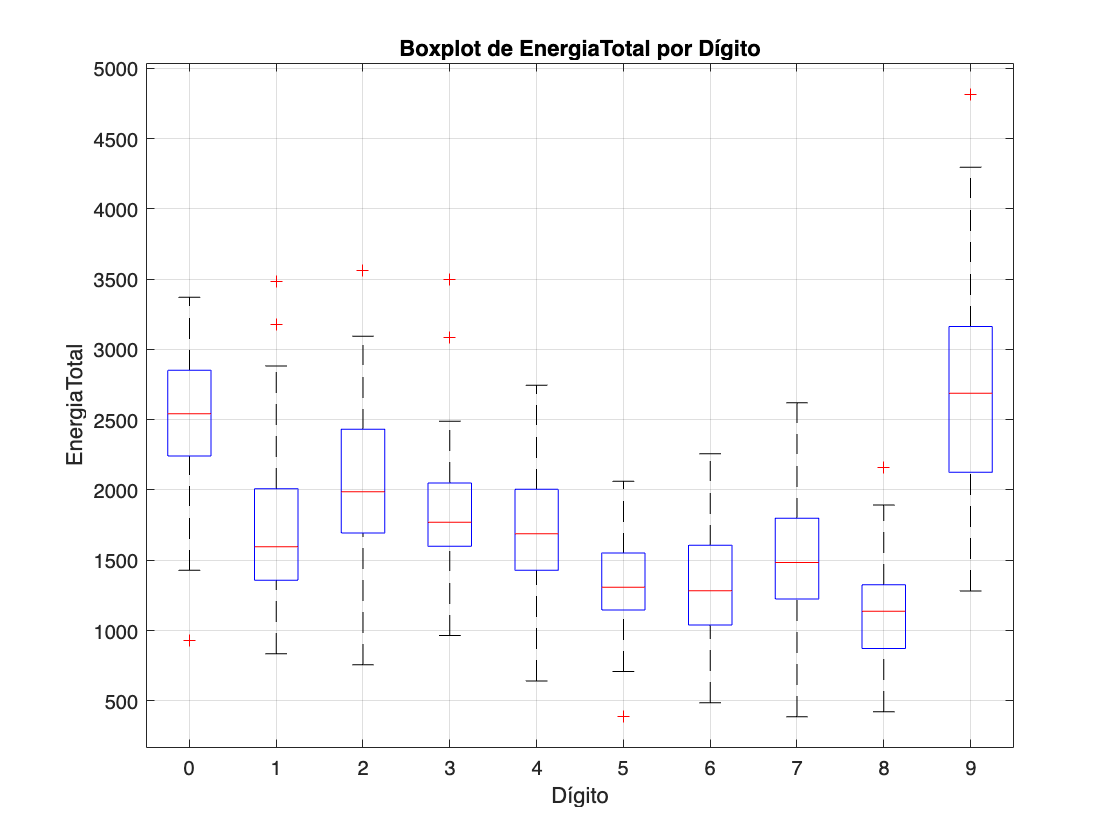

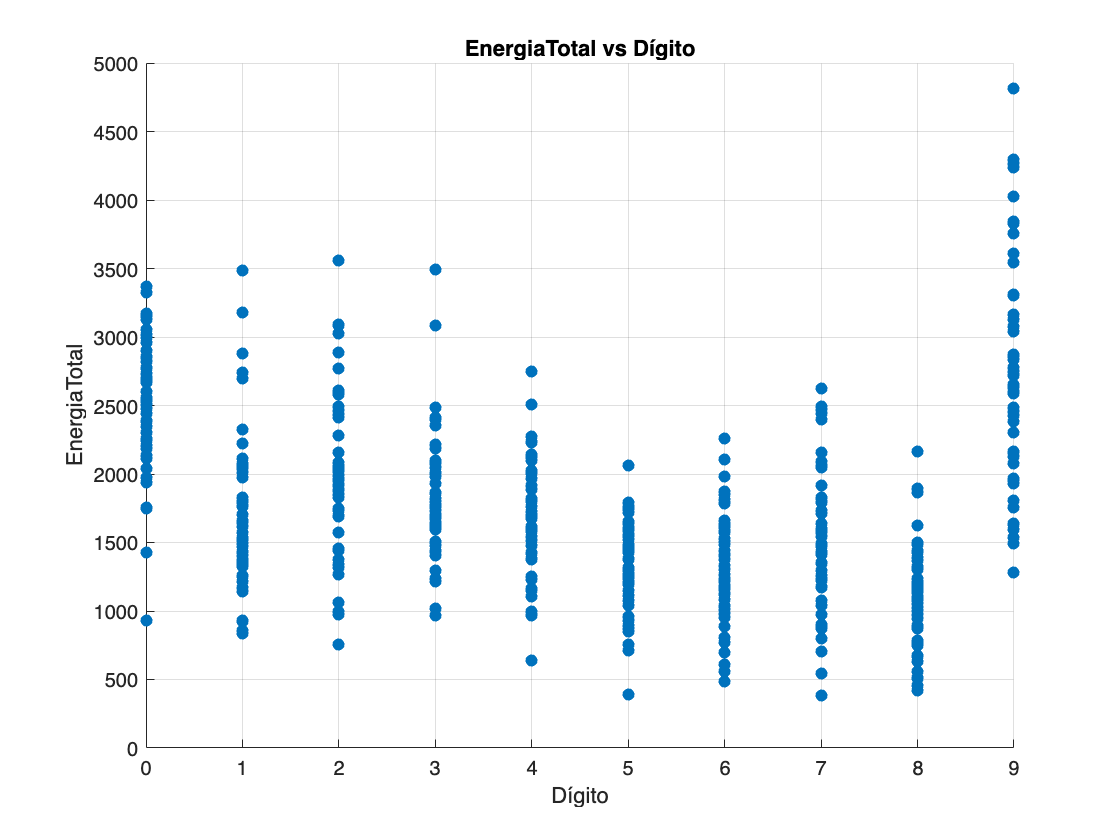

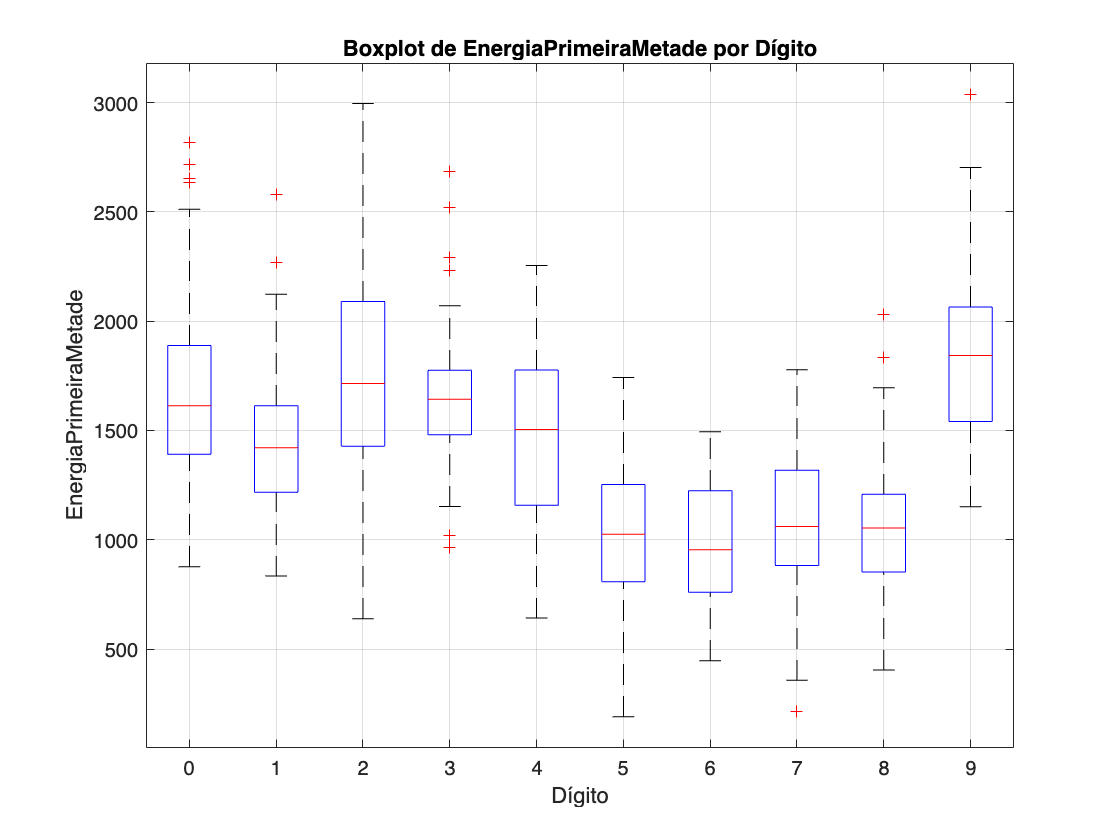

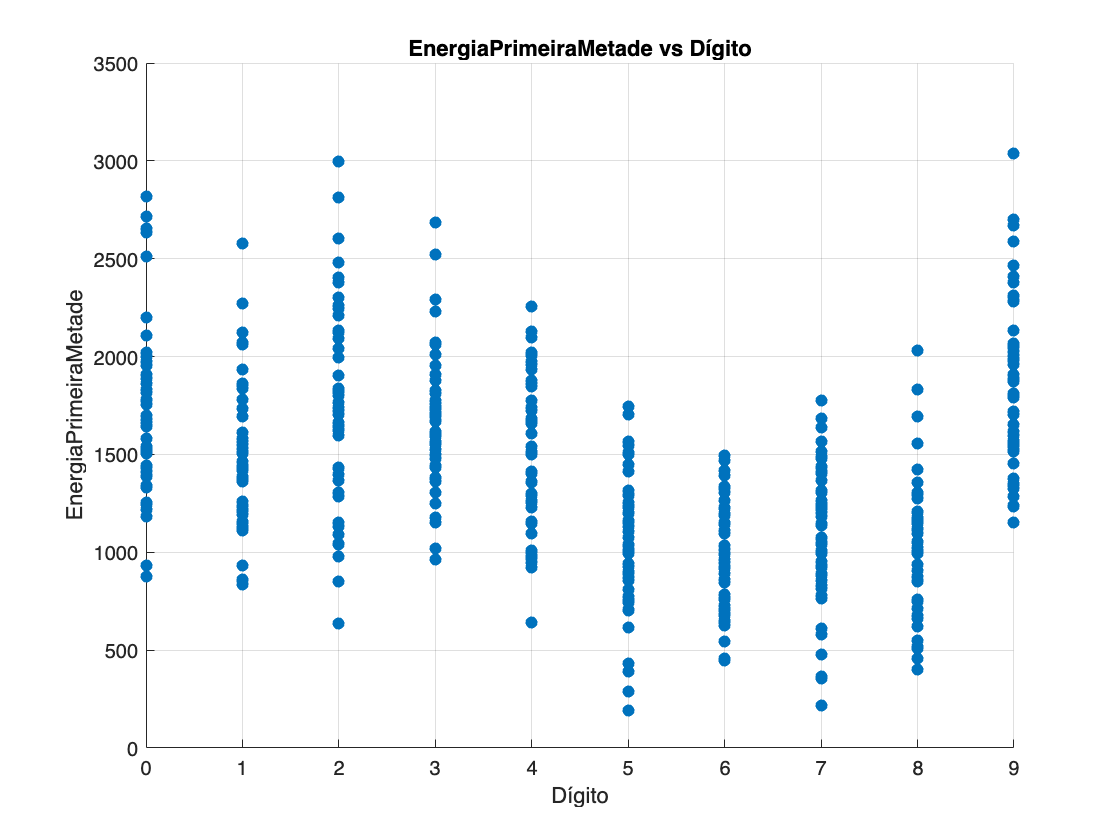

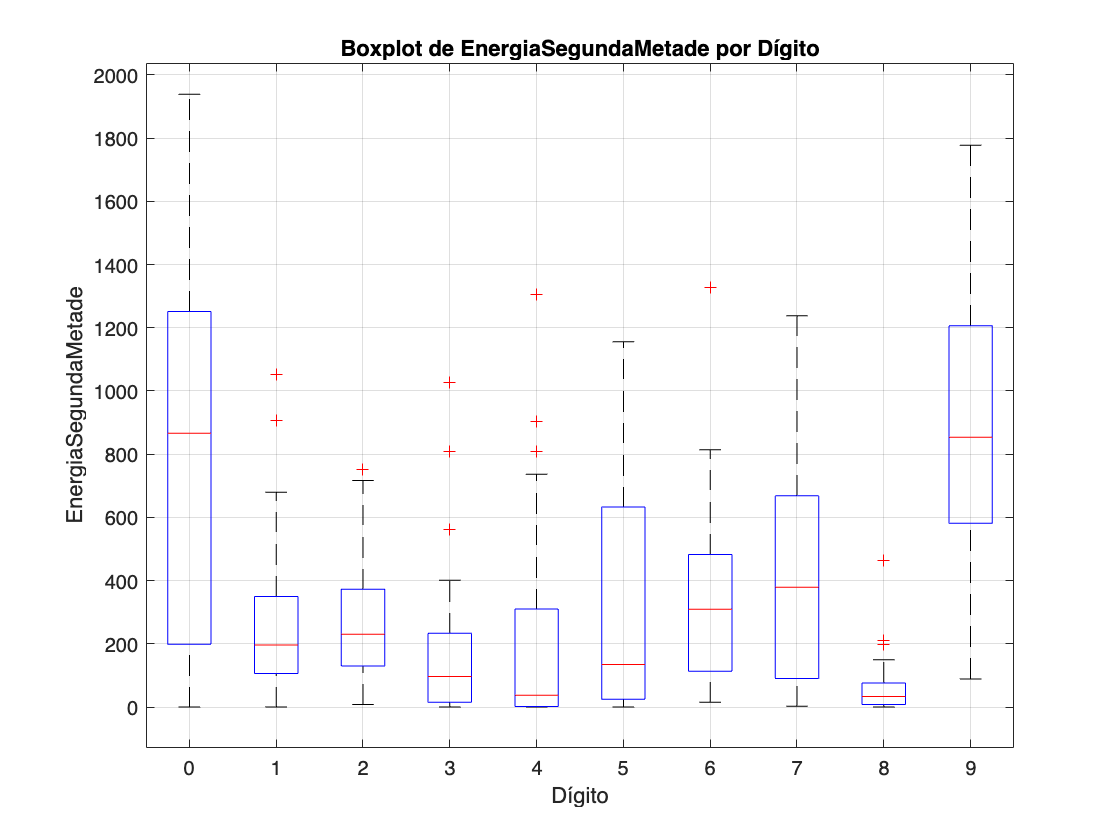

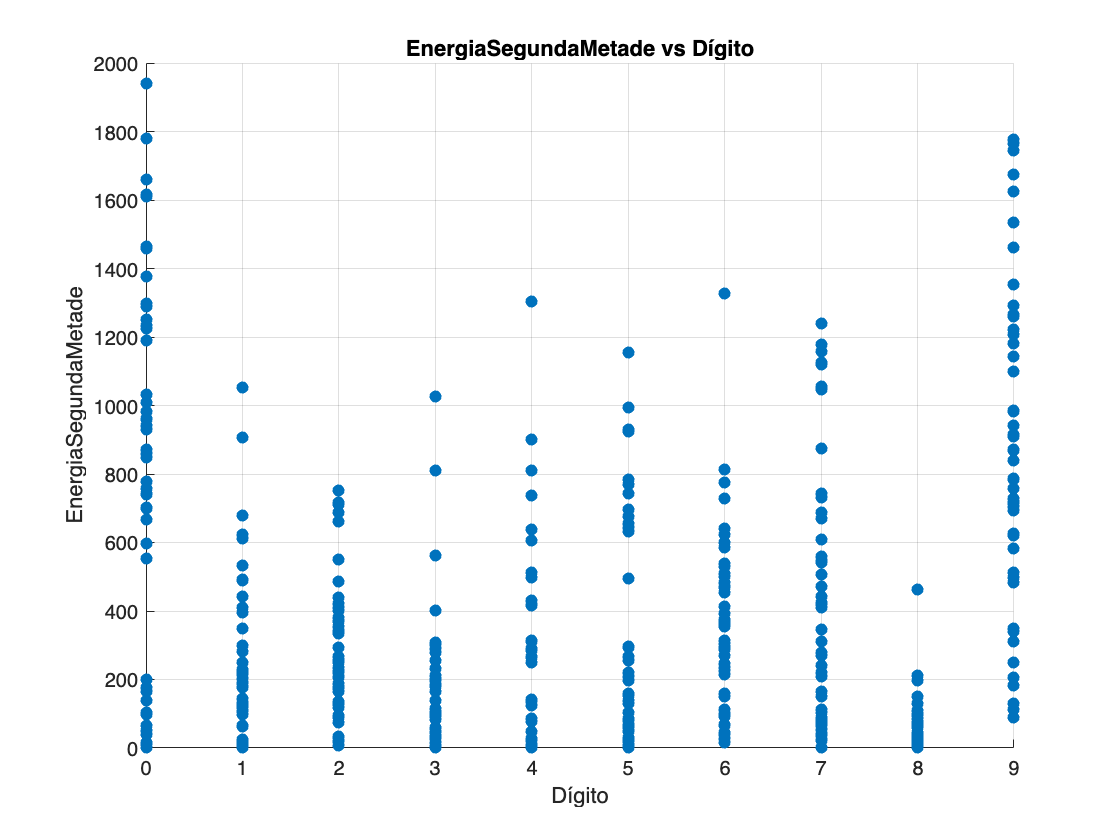

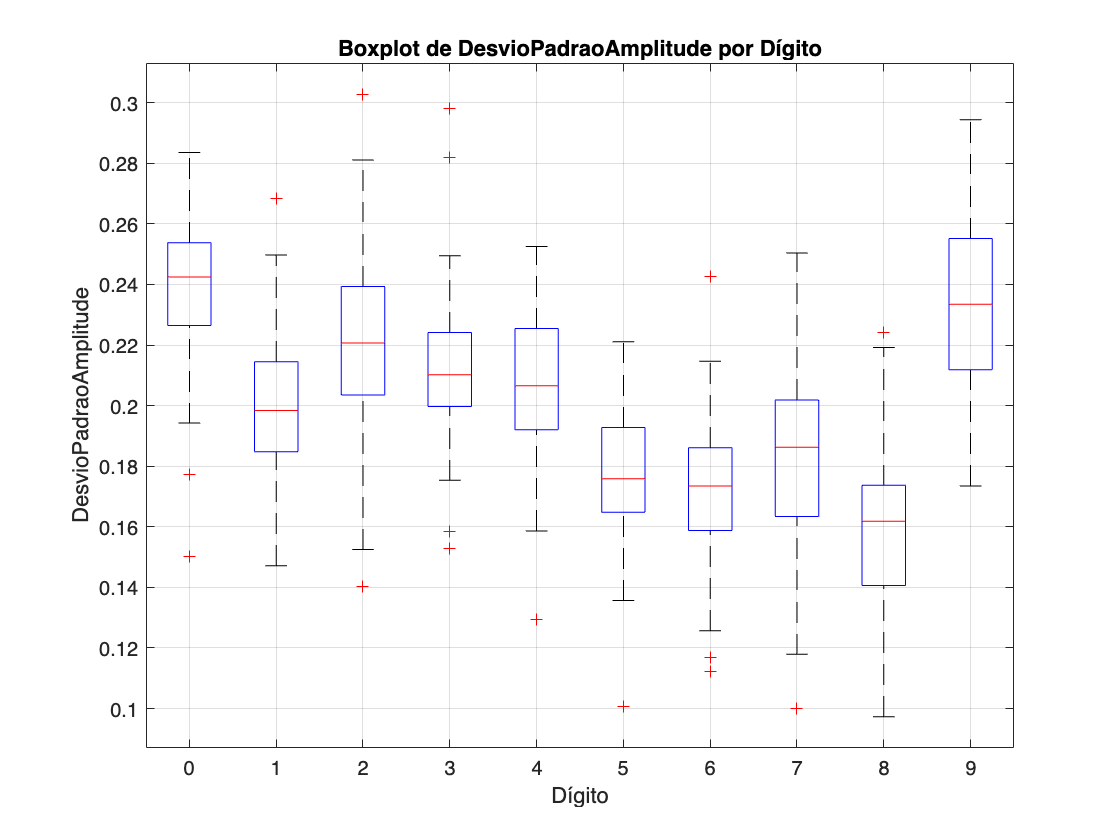

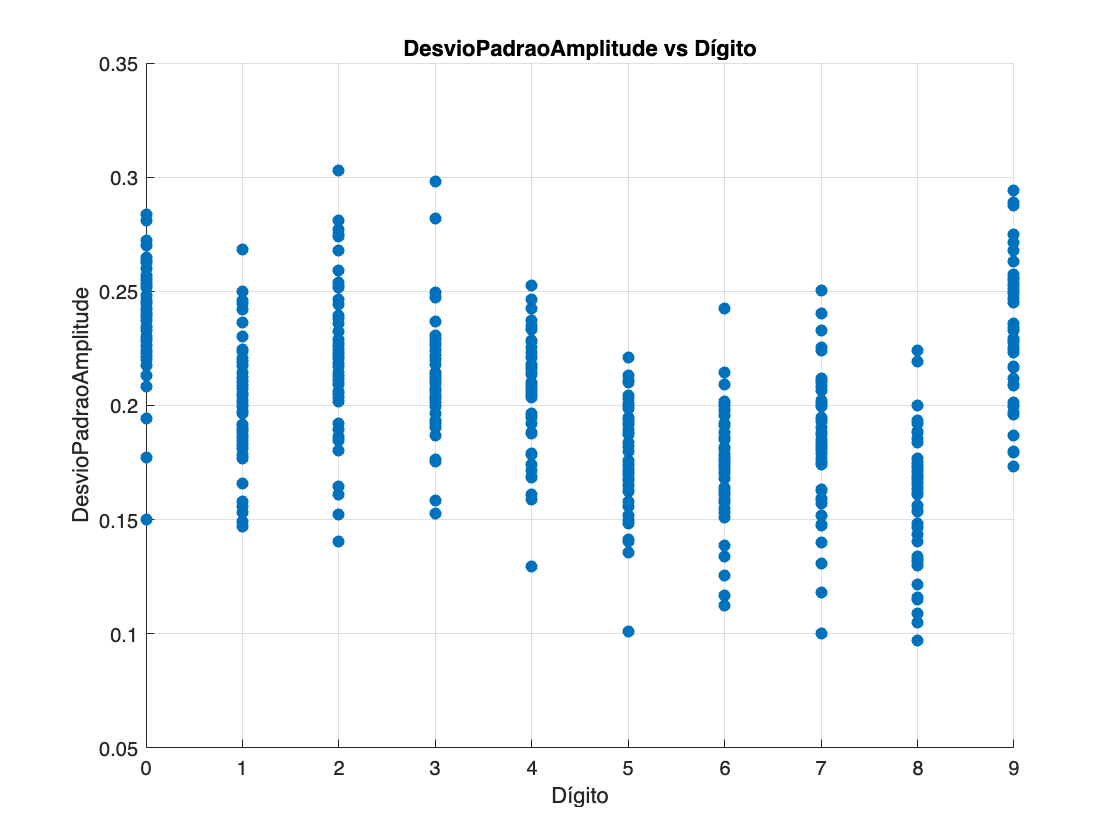


%% Ponto 8: Boxplot e Gráfico 2D para cada característica utilizada no Ponto 7

% Lista das características calculadas no Ponto 7
features = {'EnergiaTotal','EnergiaPrimeiraMetade','EnergiaSegundaMetade',...
    'DesvioPadraoAmplitude','RMS','MediaAmplitude','Fator_Crest','Taxa_Cruzamento'};

% Loop para criar os gráficos para cada característica
for i = 1:length(features)
    feat = features{i};
    
    % Boxplot: Característica vs. Dígito
    figure('Name', sprintf('Boxplot - %s por Dígito', feat), 'NumberTitle', 'off');
    boxplot(tabelaFinal.(feat), tabelaFinal.Digito);
    xlabel('Dígito');
    ylabel(feat);
    title(sprintf('Boxplot de %s por Dígito', feat));
    grid on;
    
    % Gráfico de Dispersão 2D: Característica vs. Dígito
    figure('Name', sprintf('Dispersão 2D - %s por Dígito', feat), 'NumberTitle', 'off');
    scatter(tabelaFinal.Digito, tabelaFinal.(feat), 'filled');
    xlabel('Dígito');
    ylabel(feat);
    title(sprintf('%s vs Dígito', feat));
    grid on;
end

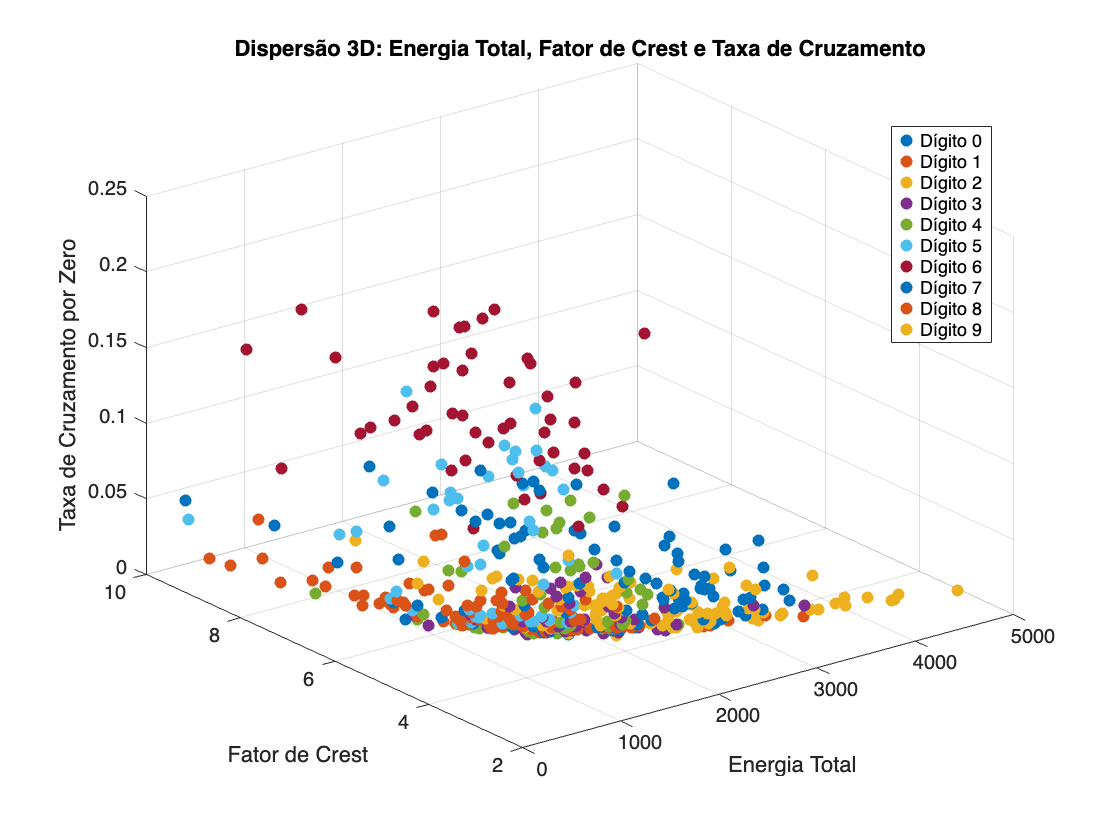



%% Gráfico 3: Dispersão 3D das características selecionadas
% Características escolhidas:
%   - Energia Total: mede a potência global do sinal.
%   - Fator de Crest: razão entre o valor máximo absoluto e o RMS, indicando picos.
%   - Taxa de Cruzamento por Zero: frequência com que o sinal cruza o zero.

% Mapear os dígitos a cores distintas
digitosUnicos = unique(tabelaFinal.Digito);
numDigitos = numel(digitosUnicos);
cores = lines(numDigitos);  % Cada linha de 'cores' é um vetor [R G B]

% Criar um array de cores para cada ponto, conforme o dígito
coresPontos = zeros(height(tabelaFinal), 3);
for i = 1:height(tabelaFinal)
    idx = find(digitosUnicos == tabelaFinal.Digito(i));
    coresPontos(i,:) = cores(idx,:);
end

% Plotar o gráfico 3D usando scatter3 com os coresPontos
figure('Name','Dispersão 3D - Características Selecionadas','NumberTitle','off');
scatter3(tabelaFinal.EnergiaTotal, tabelaFinal.Fator_Crest, tabelaFinal.Taxa_Cruzamento, 36, coresPontos, 'filled');
xlabel('Energia Total');
ylabel('Fator de Crest');
zlabel('Taxa de Cruzamento por Zero');
title('Dispersão 3D: Energia Total, Fator de Crest e Taxa de Cruzamento');
grid on;

% Criar handles fictícios para a legenda (índice de cores)
hold on;
dummyHandles = gobjects(numDigitos, 1);
for i = 1:numDigitos
    dummyHandles(i) = scatter3(NaN, NaN, NaN, 36, cores(i,:), 'filled');
end
hold off;

% Criar as entradas da legenda associando cada dígito à sua cor
entradasLegenda = arrayfun(@(d) sprintf('Dígito %d', d), digitosUnicos, 'UniformOutput', false);
legend(dummyHandles, entradasLegenda, 'Location', 'best');

## 9

save('AED1.mat', 'tabelaFinal');
